# **EVALUACIÓN 2. Trayectorias de Lazo Abierto**

**Jesús Alejandro Gómez Bautista | A01736171**

**Implementar** el código requerido para generar la trayectoria ALEJANDRO a partir del tiempo y de las velocidades angulares y lineales en un plano 2D, según corresponda. La altura de cada letra debe ser de **3m.**, el ancho puede ser ajustable **a criterio propio** y la separación entre cada letra debe ser de **0.5m.**

%% Define Vehicle
R = 0.1;                % Wheel radius [m]
L = 0.5;                % Wheelbase [m]
dd = DifferentialDrive(R,L);

%% Simulation parameters
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:2000;         % Time array

initPose = [0;0;0];             % Initial pose (x y theta)
pose = zeros(3,numel(tVec));    % Pose matrix
pose(:,1) = initPose;

% Define waypoints
%waypoints = [0,0; 1.25,3; 1.8,1.46; 0.6,1.46; 1.8,1.46; 2.5,0; 3,0; 3,3; 3,0; 5,0; 5.5,0; 5.5,3; 7.5,3; 5.5,3; 5.5,1.5; 7.5,1.5; 5.5,1.5;
             %5.5,0; 7.5,0];
 waypoints = [0,0; 0.5,0; 0.90,1; 1,1.5; 1.5,2.5; 2,1.5; 1,1.5; 0.90,1; 2.10,1; 2.50,0; 3,0; 2,3; 1,3; 0,0; 3.5,0; 3.5,3; 4,3; 4,0.5; 5,0.5; 5,0; 3.5,0; 5.5,0; 5.5,3; 7.5,3; 7.5,2.5; 6,2.5; 6,1.75; 7.5,1.75; 7.5,1.25; 6,1.25; 6,0.5; 7.5,0.5; 7.5,0; 5.5,0; 8,0; 8,1.5; 8.5,1.5; 8.5,0.5; 10,0.5; 10,3; 10.5,3;
              10.5,0; 8,0; 11,0; 11.5,0; 11.9,1; 12,1.5; 12.5,2.5; 13,1.5; 12,1.5; 11.9,1; 13.10,1; 13.50,0; 14,0; 13,3; 12,3; 11,0; 14.5,0; 14.5,3; 15,3; 16.5,0.5; 16.5,3; 17,3; 17,0; 16.5,0; 15,2.5; 15,0; 14.5,0; 17.5,0; 17.5,3; 19,3; 20,2.5; 20,0.5; 19,0; 18,0; 18,2.5; 19,2.5; 19.5,2; 19.5,1; 19,0.5; 18,0.5; 18,0; 17.5,0; 20.5,0;
              20.5,3; 23,3; 23,1.5; 21,1.5; 21,2.5; 22.5,2.5; 22.5,2; 21,2; 21,1.5; 21,0; 20.5,0; 21,0; 21,1; 22.5,0; 23,0; 21.5,1.5; 23,0; 23.5,0; 26,0; 26,3; 23.5,3; 23.5,0; 24,0; 24,0.5; 24,2.5; 25.5,2.5; 25.5,0.5; 24,0]             

waypoints =          0         0
    0.5000         0
    0.9000    1.0000
    1.0000    1.5000
    1.5000    2.5000
    2.0000    1.5000
    1.0000    1.5000
    0.9000    1.0000
    2.1000    1.0000
    2.5000         0


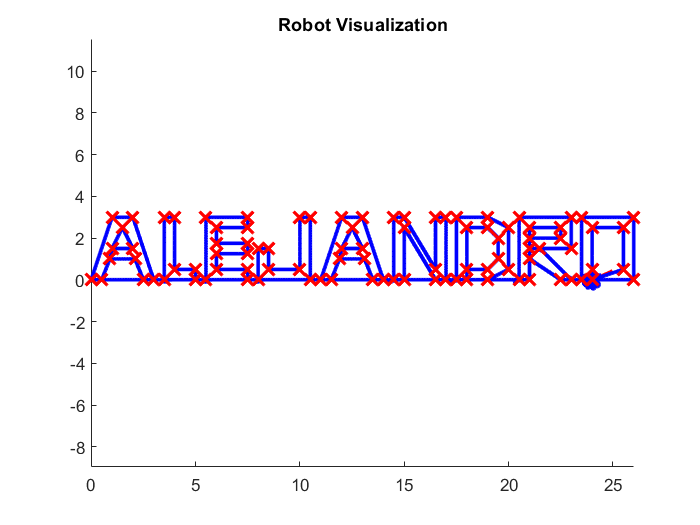


% Create visualizer
viz = Visualizer2D;
viz.hasWaypoints = true;

%% Pure Pursuit Controller
controller = controllerPurePursuit;
controller.Waypoints = waypoints;
controller.LookaheadDistance = 0.1;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 8;

%% Simulation loop
close all
r = rateControl(1/sampleTime);
for idx = 2:numel(tVec) 
    % Run the Pure Pursuit controller and convert output to wheel speeds
    [vRef,wRef] = controller(pose(:,idx-1));
    [wL,wR] = inverseKinematics(dd,vRef,wRef);
 
    
    % Compute the velocities
    [v,w] = forwardKinematics(dd,wL,wR);
    velB = [v;0;w]; % Body velocities [vx;vy;w]
    vel = bodyToWorld(velB,pose(:,idx-1));  % Convert from body to world
    
    % Perform forward discrete integration step
    pose(:,idx) = pose(:,idx-1) + vel*sampleTime; 
    
    % Update visualization
    viz(pose(:,idx),waypoints)
    waitfor(r);
    
end

Responder las siguientes preguntas en base al procedimiento empleado para obtener las trayectorias propuestas:

**a) ***¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué? *

Para realizar una trayectoria recta, basándonos en el código que emplea Waypoints para trazar las trayectorias de un robot diferencial, fue necesario aumentar mucho la velocidad angular para hacer "cambios" bruscos de dirección en un corto periodo de tiempo, mientras nos desplazábamos con una velocidad lineal relativamente baja para realizar dichos cambios sin necesidad de dar una curva prolongada resultado de una velocidad lineal alta. Así mismo, para evitar trazos deformados o cortes abruptos que atravesaran las letras, decidí recorrer el mayor número de waypoints posibles para preservar estos trazos.

***b)**** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?*

Para una trayectoria curva dada la naturaleza del código sería un poco complicado más no imposible, aunque claro, no quedarían del todo "curvos", el parámetro que permitiría esto no sería otro que el propio valor de la velocidad angular, sin embargo, como puede apreciarse, en mi caso no fue influyo mucho una velocidad angular grande para generar trazos curvos debido a la velocidad lineal tan baja. Así mismo, los waypoints servirían mucho para esta labor.

***c) ****¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?*

La velocidad angular nos permite girar en nuestro código, tal y como lo mencioné líneas arriba, dado que buscábamos trazos rectos, hicimos que el valor de la velocidad angular fuera considerablemente elevado frente a la velocidad lineal para hacer giros en tiempos cortos sin tanta curvatura.

***d) ****¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?*

Determina el tiempo de ejecución de nuestro robot, es decir, el tiempo que mantendrá la trayectoria hasta que este se consuma, podrá prolongarse gracias al paso o ts que decidamos, un ts pequeño dividirá aún más el tiempo de ejecución y hará mucho más preciso nuestro recorrido, pues el sample time corto hace que nuestro robot haga su recorrido punto a punto, considerando muchas divisiones entre ellos.

**e)** *¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?*

En este caso, los waypoints fueron aquellos que incurrieron en las longitudes y dimensiones de nuestras letras, por lo que, si buscabamos precisión en el trazo, debiamos ser especialmente detallados en los puntos que deseabamos trazar.